# Backtest Investment Strategies For Investment Roboadvisor

Perform backtesting of portfolio strategies using a backtesting framework. Backtesting is a useful tool to compare how investment strategies perform over historical or simulated market data. This example develops five different investment strategies and then compares their performance after running over a one-year period of historical stock data. The backtesting framework is implemented in two Financial Toolbox™ classes: [backtestStrategy](docid:finance_ug.object_backtest_strategy) and [backtestEngine](docid:finance_ug.object_backtest_engine).    

## Load Data

% Read a table of daily adjusted close prices for ETFs.
T = readtable('ETF_data_20161206_20231031.xlsx', VariableNamingRule='preserve');

assetSymbols = ["SPY US Equity", "IWR US Equity", "IWM US Equity", "VGK US Equity","AIA US Equity",...
    "XLK US Equity", "XLV US Equity", "XLF US Equity", "XLRE US Equity", "XLY US Equity",...
    "XLP US Equity", "XLE US Equity", "XLI US Equity", "XLB US Equity", "XLU US Equity",...
    "GOVT US Equity", "LQD US Equity", "JNK US Equity", "GLD US Equity", "USO US Equity",...
    "DBA US Equity", "ACWX US Equity", "EEM US Equity", "ESGU US Equity", "ROBO US Equity",...
    "XBI US Equity", "SHV US Equity"];

% Prune the table to hold only the dates and ETFs.
timeColumn = "Dates";
T = T(:,[timeColumn assetSymbols]);

% Convert to the table to a timetable.
pricesTT = table2timetable(T,'RowTimes','Dates');

% View the structure of the prices timetable.
head(pricesTT)

       Dates       SPY US Equity    IWR US Equity    IWM US Equity    VGK US Equity    AIA US Equity    XLK US Equity    XLV US Equity    XLF US Equity    XLRE US Equity    XLY US Equity    XLP US Equity    XLE US Equity    XLI US Equity    XLB US Equity    XLU US Equity    GOVT US Equity    LQD US Equity    JNK US Equity    GLD US Equity    USO US Equity    DBA US Equity    ACWX US Equity    EEM US Equity    ESGU US Equity    ROBO US Equity    XBI US Equity    SHV US Equity
    ___________    

% View the size of the asset price data set.
numSample = size(pricesTT.Variables, 1);
numAssets = size(pricesTT.Variables, 2);
table(numSample, numAssets) 

ans = 1×2 table
    numSample    numAssets
    _________    _________

      1801          27    


**Load user information**

% Declare the variables as global
global expected_return target_volatility minWeightslist maxWeightslist
user_information = readtable('user_information.xlsx', VariableNamingRule='preserve')

user_information = 1×9 table
    Money Budget    Investment For     Investment Plan      Risk Tolerance                          Investment Period                        Preferred Industry    Industry Preference    Emergency Money    Expected Return
    ____________    _______________    _______________    __________________    _________________________________________________________    __________________    ___________________    _______________    _______________

     {'20000'}      {'pay tuition'}     {'long-term'}     {'15% volatility'}    {'over 5 years with volatility adjustment factor is 1.3'}       {'finance'}        {'31%-50% weight'}        {'20000'}           {'30'}     


% Extract the string from the cell array
expected_return_string = user_information.('Expected Return'){1};
expected_return_string = strrep(expected_return_string, '%', '');
expected_return = str2double(expected_return_string) / 100

expected_return = 0.3000

% Extract money ratio
money_budget_string = user_information.('Money Budget'){1};
emergency_money_string = user_information.('Emergency Money'){1};
money_budget_string = strrep(money_budget_string, '''', '');
emergency_money_string = strrep(emergency_money_string, '''', '');
money_budget_numeric = str2double(money_budget_string);
emergency_money_numeric = str2double(emergency_money_string);
cash_ratio = emergency_money_numeric./ money_budget_numeric * 0.8

cash_ratio = 0.8000

% Extract risk tolerance string
risk_tolerance_string = user_information.('Risk Tolerance'){1};

% Use regular expressions to extract the percentage
pattern = '\d+\.?\d*%';
vol = regexp(risk_tolerance_string, pattern, 'match');
percentage_string = vol{1};
percentage_string = strrep(percentage_string, '%', '');
vol_numeric = str2double(percentage_string)/100

vol_numeric = 0.1500

% Extract volatility adjustment factor
investment_period_string = user_information.('Investment Period'){1};  
pattern = '(?<=factor is )\d+\.?\d*';
factor_match = regexp(investment_period_string, pattern, 'match');
factor_numeric = str2double(factor_match{1})

factor_numeric = 1.3000

% Define target volatility
target_volatility = vol_numeric * factor_numeric

target_volatility = 0.1950

% Map and extract the weights for each ETF
% Define the mapping of sectors to ETF symbols
sectorToSymbolMap = containers.Map({
    'technology', 'healthcare', 'finance', 'real estate', 'consumer discretionary',...
    'consumer staples', 'energy', 'industrials', 'materials', 'communication services',...
    'utilities', 'government', 'corporate', 'high-yield bonds', 'gold',...
    'oil', 'agricultural products', 'international', 'emerging markets', 'esg',...
    'ai & technology', 'biotech'},...
    {'XLK US Equity', 'XLV US Equity', 'XLF US Equity', 'XLRE US Equity', 'XLY US Equity',...
    'XLP US Equity', 'XLE US Equity', 'XLI US Equity', 'XLB US Equity', 'XLC US Equity',...
    'XLU US Equity', 'GOVT US Equity', 'LQD US Equity', 'JNK US Equity', 'GLD US Equity',...
    'USO US Equity', 'DBA US Equity', 'ACWX US Equity', 'EEM US Equity', 'ESGU US Equity',...
    'ROBO US Equity', 'XBI US Equity'});

preferredIndustry = user_information.('Preferred Industry'){1};  % Extracting 'Preferred Industry'
industryPreferenceString = user_information.('Industry Preference'){1};  % Extracting 'Industry Preference'

% Extract the minimum and maximum weight values from the industry preference string
pattern = '(\d+)%-(\d+)%';
weights = regexp(industryPreferenceString, pattern, 'tokens');
weights = str2double(weights{1});  % Convert from cell array of strings to numeric array

% Initialize the minWeights and maxWeights with zeros and ones respectively
minWeightslist = zeros(size(assetSymbols));
maxWeightslist = ones(size(assetSymbols));

% Set the minimum and maximum weights for the preferred industry ETF
% Find the index of the preferred industry ETF symbol in the assetSymbols array
preferredETFIndex = find(assetSymbols == sectorToSymbolMap(preferredIndustry));

% Set the minimum and maximum weights for the preferred industry ETF
minWeightslist(preferredETFIndex) = weights(1) / 100; % Converting percentage to decimal
% Set the last element of the minWeights array to cash_ratio
minWeightslist(end) = cash_ratio

minWeightslist =          0         0         0         0         0         0         0    0.3100         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.8000


maxWeightslist(preferredETFIndex) = weights(2) / 100 % Converting percentage to decimal

maxWeightslist =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.5000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


## Compute Initial Strategy Weights

Use the strategy rebalance functions to compute the initial weights for each strategy. Setting the initial weights is important because otherwise the strategies begin the backtest with 100% in cash, earning the risk-free rate, until the first rebalance date.

We use the first 63 days of the data set (about 3 months) to initialize the strategies. The backtest is then run over the remaining data.

The initial weights are calculated by calling the [backtestStrategy](docid:finance_ug.object_backtest_strategy) rebalance function in the same way that the backtesting engine will call it. To do so, pass in a vector of current weights (all zeros, that is 100% cash) as well as a window of price data that the strategies will use to set the desired weights (the warm-up data partition). Using the rebalance functions to compute the initial weights in this way is not required. The initial weights are a vector of the initial portfolio weights and can be set to any appropriate value. The rebalance functions in this example approximate the state the strategies would be in had they been already running at the start of the backtest.

warmupPeriod = 63;
% No current weights (100% cash position).
current_weights = zeros(1,numAssets);

% Warm-up partition of data set timetable.
warmupTT = pricesTT(1:warmupPeriod,:);

% Compute the initial portfolio weights for each strategy.
constrainedOptim_initial = constrainedOptimFcn(current_weights,warmupTT);
markowitz_initial       = markowitzFcn(current_weights,warmupTT);
robustOptim_initial     = robustOptimFcn(current_weights,warmupTT);

Visualize the initial weight allocations from the strategies.

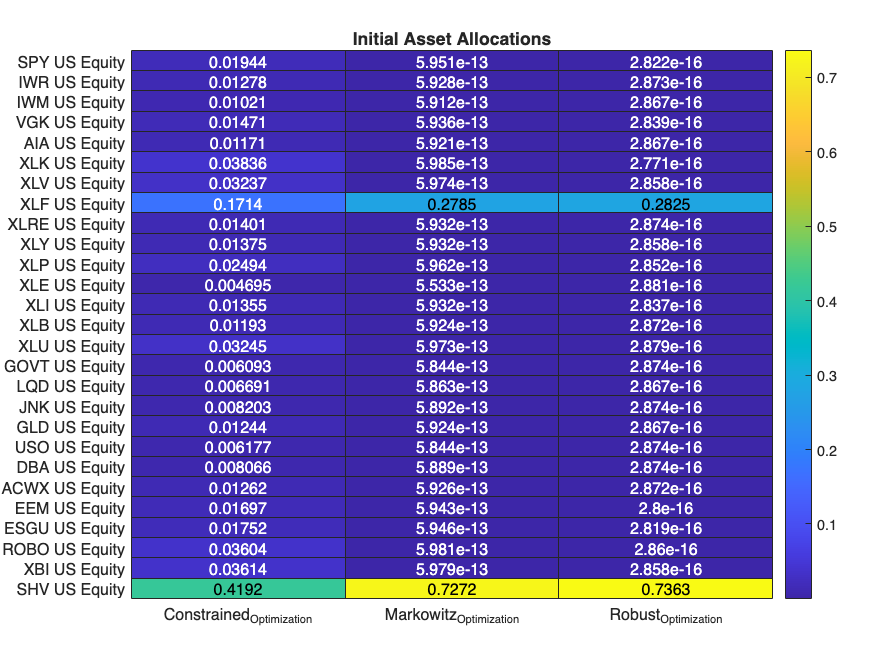

strategyNames = {'Constrained_Optimization', 'Markowitz_Optimization','Robust_Optimization'};
assetSymbols = pricesTT.Properties.VariableNames;
initialWeights = [constrainedOptim_initial(:), markowitz_initial(:), robustOptim_initial(:)];
heatmap(strategyNames, assetSymbols, initialWeights, 'title','Initial Asset Allocations','Colormap', parula)

## Create Backtest Strategies

To use the strategies in the backtesting framework, you must build [backtestStrategy](docid:finance_ug.object_backtest_strategy) objects, one for each strategy. The [backtestStrategy](docid:finance_ug.object_backtest_strategy) function takes as input the strategy name and rebalancing function for each strategy. Additionally, the [backtestStrategy](docid:finance_ug.object_backtest_strategy) can take a variety of name-value pair arguments to specify various options.  For more information on creating backtest strategies, see [backtestStrategy](docid:finance_ug.object_backtest_strategy).

Set the rebalance frequency and lookback window size are set in terms of number of time steps (that is, rows of the `pricesTT` timetable).  Since the data is daily price data, specify the rebalance frequency and rolling lookback window in days.

% Rebalance approximately every 3 months (252 / 12 = 21).
rebalFreq = 63;

% Set the rolling lookback window to be at least 42 days and at most 126
% days (about 6 months).
lookback  = [42 126];

% Use a fixed transaction cost (buy and sell costs are both 0.5% of amount
% traded).
transactionsFixed = 0.005;

% Customize the transaction costs using a function. See the
% variableTransactionCosts function below for an example.
transactionsVariable = @variableTransactionCosts;

% The first two strategies use fixed transaction costs. The equal-weighted
% strategy does not require a lookback window of trailing data, as its
% allocation is fixed.

strat1 = backtestStrategy('Constrained Optimization', @constrainedOptimFcn, ...
    'RebalanceFrequency', rebalFreq, ...
    'LookbackWindow', lookback, ...
    'TransactionCosts', transactionsFixed, ...
    'InitialWeights', constrainedOptim_initial);

strat2 = backtestStrategy('Markowitz Optimization', @markowitzFcn, ...
    'RebalanceFrequency', rebalFreq, ...
    'LookbackWindow', lookback, ...
    'TransactionCosts', transactionsFixed, ...
    'InitialWeights', markowitz_initial);

strat3 = backtestStrategy('Robust Optimization', @robustOptimFcn, ...
    'RebalanceFrequency', rebalFreq, ...
    'LookbackWindow', lookback, ...
    'TransactionCosts', transactionsFixed, ...
    'InitialWeights', robustOptim_initial);

% Aggregate the strategy objects into an array.
strategies = [strat1, strat2, strat3];

## Backtest the Strategies

Use the following the workflow to backtest the strategies with a [backtestEngine](docid:finance_ug.object_backtest_engine).

#### Define And Run Backtesting Engine

% Risk-free rate is 1% annualized
annualRiskFreeRate = 0.01;

% Create the backtesting engine object
backtester = backtestEngine(strategies, 'RiskFreeRate', annualRiskFreeRate);

% Run Backtest
backtester = runBacktest(backtester, pricesTT, 'Start', warmupPeriod);

## Examine Backtest Results

Use the [summary](docid:finance_ug.function_backtestsummary) function to generate a table of strategy performance results for the backtest.

summaryByStrategies = summary(backtester)

summaryByStrategies = 9×3 table
                       Constrained_Optimization    Markowitz_Optimization    Robust_Optimization
                       ________________________    ______________________    ___________________

    TotalReturn                  0.12123                     0.1038                 0.10387     
    SharpeRatio                0.0089455                  0.0066417               0.0066602     
    Volatility                  0.003946                  0.0039723               0.0039587     
    AverageTurnover            0.0004585                 0.00022371              0.00021956     
    MaxTurnover                  0.28416                   0.068401                0.065195     
    AverageReturn             7.3632e-05                 6.4718e-05              6.4

Compare the total return of each strategy and select the best one.

% Assume 'summaryByStrategies' is your table variable
totalReturns = summaryByStrategies{'TotalReturn', :}; % Extract the 'TotalReturn' row

% Find the maximum return and the index of that return
[bestReturn, bestIdx] = max(totalReturns);

% Extract the strategy names (column headers)
strategyNames = summaryByStrategies.Properties.VariableNames;

% Get the name of the best strategy using the index
bestStrategyName = strategyNames{bestIdx}

bestStrategyName = 'Constrained_Optimization'

% Extract all metrics for the best strategy
bestStrategyMetrics = summaryByStrategies(1:7, bestStrategyName)

bestStrategyMetrics = 7×1 table
                       Constrained_Optimization
                       ________________________

    TotalReturn                  0.12123       
    SharpeRatio                0.0089455       
    Volatility                  0.003946       
    AverageTurnover            0.0004585       
    MaxTurnover                  0.28416       
    AverageReturn             7.3632e-05       
    MaxDrawdown                  0.11906       


% Save bestStrategyMetrics to local
writetable(bestStrategyMetrics, 'OUTPUT_1_bestStrategyMetrics.csv', 'WriteRowNames', true);

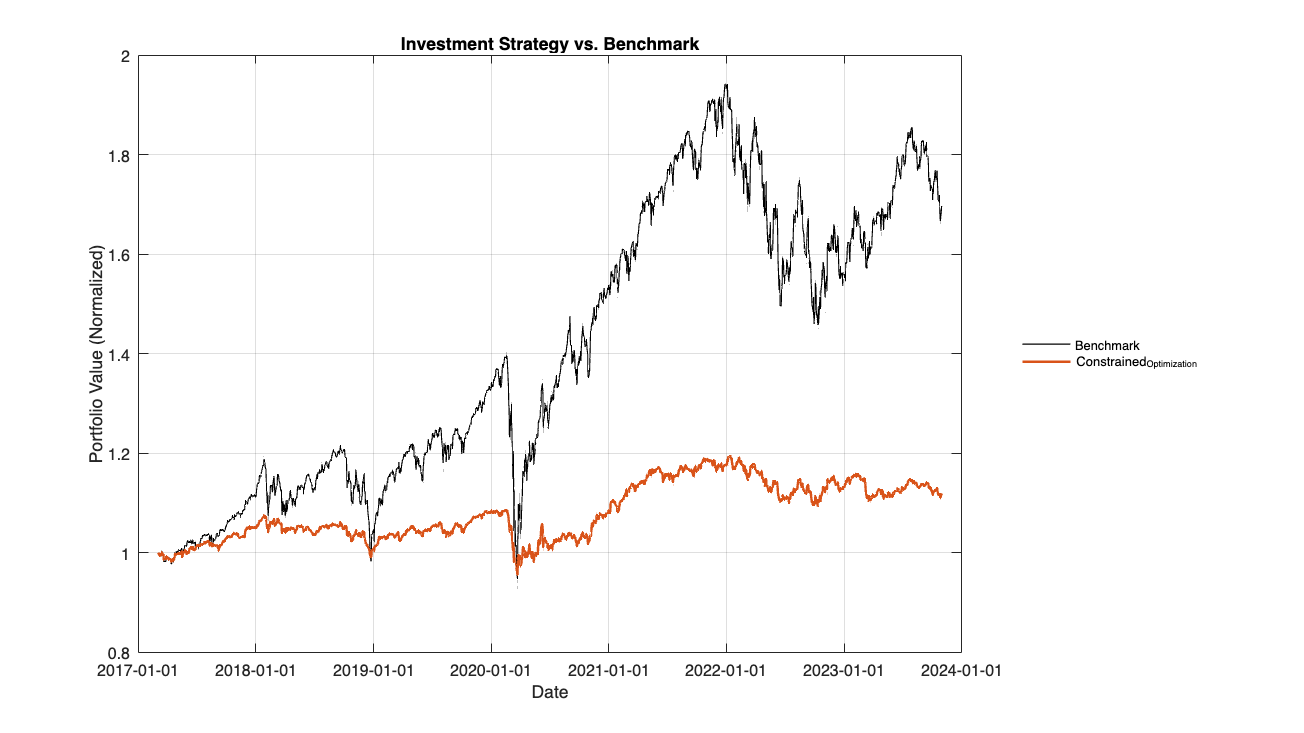

% equityCurve(backtester)
% Display the chart for the best strategy and benchmark
plotBenchmarkAndStrategies(backtester, pricesTT, warmupPeriod, bestStrategyName);
% Save the chart
exportgraphics(gcf, 'OUTPUT_2_StrategyPlot.png') % Export the figure to a PNG file

% Generate historical daily net value data of the benchmark and portfolio
PortfolioDailyHistoricalData = generateDailyDataTable(backtester, pricesTT, warmupPeriod, bestStrategyName);
% Save bestStrategyMetrics to local
writetable(PortfolioDailyHistoricalData, 'OUTPUT_2_PortfolioDailyHistoricalData.csv', 'WriteRowNames', true);

Output the latest assets allocation weights for each strategy.

% Initialize the first rebalance date just after the warmup period
currentDate = pricesTT.Dates(warmupPeriod + 1);
endDate = pricesTT.Dates(end);
rebalanceDates = currentDate; % Start with the first rebalance date

% Assuming 'rebalFreq' is defined somewhere in your code
% Add your definition of 'rebalFreq' here

% Loop to find all rebalance dates within the range
while currentDate <= endDate
    % Find the index of currentDate in pricesTT.Dates
    currentDateIdx = find(pricesTT.Dates == currentDate);
    % Calculate the index for the next rebalance date
    nextDateIdx = currentDateIdx + rebalFreq;
    
    % If the nextDateIdx is within the bounds of pricesTT.Dates
    if nextDateIdx <= height(pricesTT)
        % Add the date to rebalanceDates
        currentDate = pricesTT.Dates(nextDateIdx);
        rebalanceDates = [rebalanceDates; currentDate];
    else
        % If the nextDateIdx is out of bounds, exit the loop
        break;
    end
end

% The last rebalance date is the penultimate date in rebalanceDates
% since the last date might exceed the endDate
lastRebalanceDate = rebalanceDates(end-1);

% Initialize a table to store the strategy, asset, and their respective weights
weightsTable = table();

% Get the index of the last rebalance date in 'pricesTT.Dates'
lastRebalanceIdx = find(pricesTT.Dates == lastRebalanceDate, 1, 'first');

% Check if the index is found
if ~isempty(lastRebalanceIdx)
    % Extract the positions for the last rebalance date for the best strategy
    strategyPositions = backtester.Positions.(bestStrategyName){lastRebalanceIdx, :};

    % Calculate the portfolio weights and round them to two decimals
    totalValue = sum(strategyPositions);
    strategyWeights = round(strategyPositions / totalValue, 2);

    % Get asset names
    assetNames = backtester.Positions.(bestStrategyName).Properties.VariableNames;

    % Populate the table for each asset in the best strategy
    for j = 1:length(assetNames)
        newRow = {bestStrategyName, datetime(lastRebalanceDate), assetNames{j}, strategyWeights(j)};
        weightsTable = [weightsTable; newRow];
    end
else
    disp(['No rebalance data found for ' bestStrategyName ' on ' datestr(lastRebalanceDate)]);
end

% Rename the table columns
weightsTable.Properties.VariableNames = {'Strategy', 'RebalanceDate', 'Asset', 'Weight'};

% Display the table
disp(weightsTable);

              Strategy              RebalanceDate          Asset           Weight
    ____________________________    _____________    __________________    ______

    {'Constrained_Optimization'}     14-Jun-2023     {'Cash'          }        0 
    {'Constrained_Optimization'}     14-Jun-2023     {'SPY US Equity' }        0 
    {'Constrained_Optimization'}     14-Jun-2023     {'IWR US Equity' }        0 
    {'Constrained_Optimization'}     14-Jun-2023     {'IWM US Equity' }        0 
    {'Constrained_Optimization'}     14-Jun-2023     {'VGK US Equity' }        0 
    {'Constrained_Optimization'}     14-Jun-2023     {'AIA US Equity' }        0 
    {'Constrained_Optimization'}     14-Jun-2023     {'XLK US Equity' }        0 
    {'Constrained_Optimization'}     14-Jun-2023     {'XLV US Equity' }        0 
    {'Constrained_Optimization'}     14-Jun

% Save weightsTable to local
writetable(weightsTable, 'OUTPUT_3_weightsTable.csv', 'WriteRowNames', true);

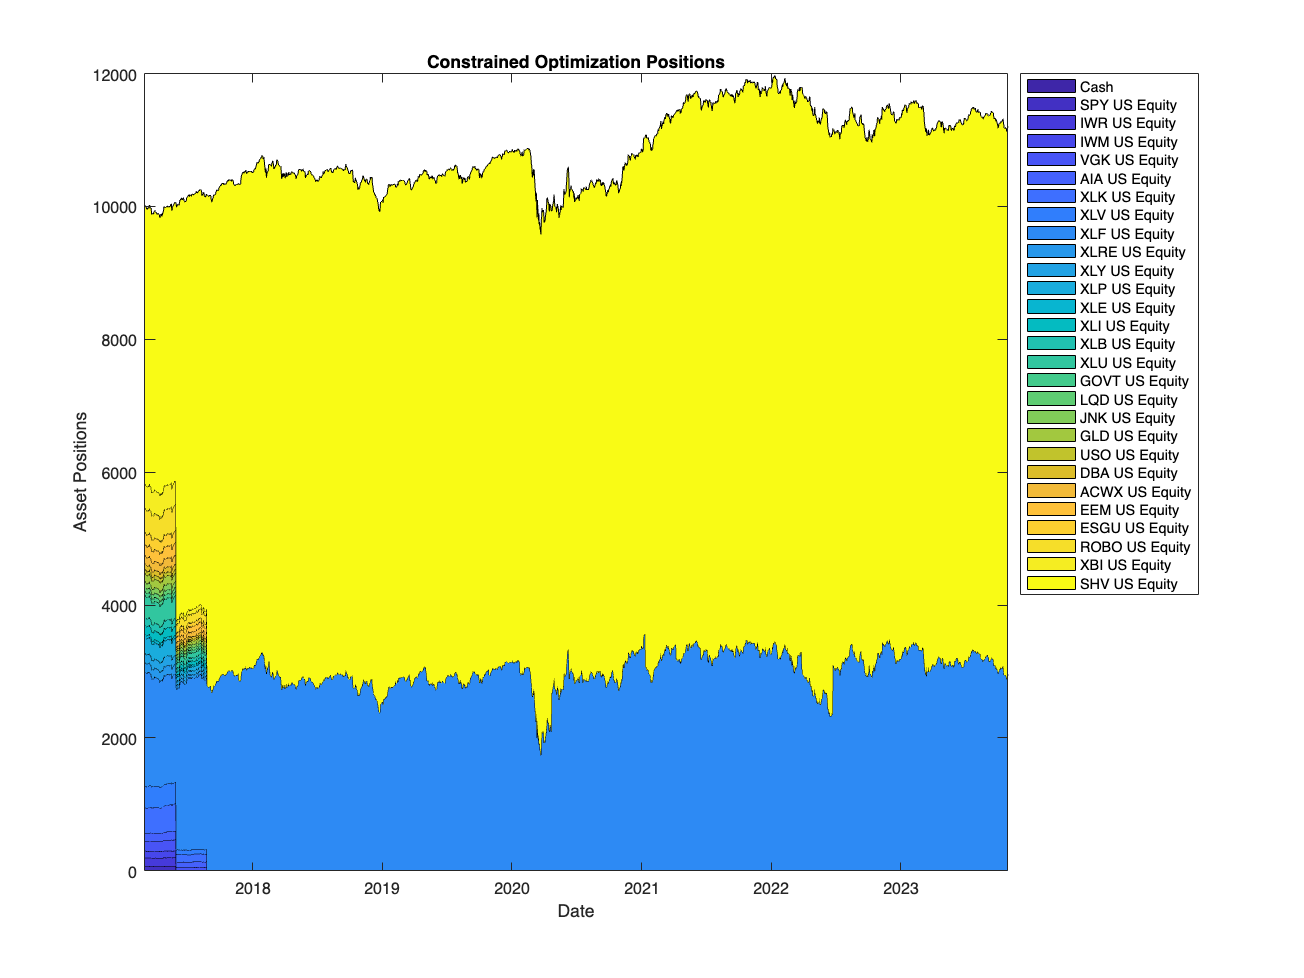

% Plot chart for historical allocation
assetAreaPlot(backtester,bestStrategyName)
% Save the chart
exportgraphics(gcf, 'OUTPUT_4_assetAreaPlot.png') % Export the figure to a PNG file

## Local Functions

function new_weights = constrainedOptimFcn(current_weights, pricesTT)
    % Declare the same variables as global within the function
    global expected_return target_volatility minWeightslist maxWeightslist

    % Simplified Portfolio Constraints Optimization
    nAssets = size(pricesTT, 2);
    assetReturns = tick2ret(pricesTT);
    
    % Covariance matrix of asset returns
    Q = cov(table2array(assetReturns));
    
    % Average returns
    rPortfolio = mean(table2array(assetReturns))';

    % Optimization problem
    pConstrained = optimproblem('Description','Constrained Portfolio');

    % Define the variables
    xConstrained = optimvar('x', nAssets, 1, 'Type', 'continuous', 'LowerBound', 0, 'UpperBound', 1);
    
    % Define risk aversion coefficient variable
    lambda = optimvar('lambda', 1, 1, 'LowerBound', 0, 'UpperBound', 1);

    % Define the volatility constraint
    annualizedVolatility = target_volatility;
    maxVolatility = annualizedVolatility / sqrt(252);

    % Volatility of the portfolio
    portfolioVolatility = sqrt(xConstrained'*Q*xConstrained);

    % Define specific weight constraints for each asset
    minWeights = minWeightslist; % specify minimum weights for each asset
    maxWeights = maxWeightslist;  % specify maximum weights for each asset

    for i = 1:nAssets
        pConstrained.Constraints.(['minWeight' num2str(i)]) = xConstrained(i) >= minWeights(i);
        pConstrained.Constraints.(['maxWeight' num2str(i)]) = xConstrained(i) <= maxWeights(i);
    end

    % Budget constraint
    pConstrained.Constraints.budget = sum(xConstrained) == 1;


    % Expected return constraint with shortfall consideration
    annualizedReturn = expected_return;
    targetReturn = (1 + annualizedReturn)^(1/4) - 1;  % Quarterly target return
    % pMrkwtz.Constraints.shortfall = shortfallVar >= targetReturn - rPortfolio'*xMrkwtz;

    % Penalty factor for shortfall
    penaltyFactor = 10000;

    % Optional: Constraint on deviation from current weights
    maxDeviation = 0.05; % Maximum allowed deviation from current weights
    for i = 1:nAssets
        pConstrained.Constraints.(['minDeviation' num2str(i)]) = ...
            xConstrained(i) >= current_weights(i) - maxDeviation;
        pConstrained.Constraints.(['maxDeviation' num2str(i)]) = ...
            xConstrained(i) <= current_weights(i) + maxDeviation;
    end

    % Define the objective function (Maximize returns, minimize risk)
    pConstrained.Objective = -rPortfolio'*xConstrained + lambda * xConstrained'*Q*xConstrained+...
        penaltyFactor * (targetReturn - rPortfolio'*xConstrained) + ...   % shortfallVar
        penaltyFactor * (portfolioVolatility - maxVolatility)^2;

    % Initial guesses based on current weights
    x0.x = repmat(1/nAssets, nAssets, 1);
    x0.lambda = 0.5;  % Initial guess for lambda

    % Set optimization options
    opt = optimoptions('fmincon','Display','off');

    % Solve the optimization problem
    [solConstrained,~,~] = solve(pConstrained, x0, 'Options', opt);

    % Output the optimized weights
    new_weights = solConstrained.x;
end

function new_weights = robustOptimFcn(current_weights, pricesTT)
    % Declare the same variables as global within the function
    global expected_return target_volatility minWeightslist maxWeightslist

    % Robust portfolio allocation
    nAssets = size(pricesTT, 2);
    assetReturns = tick2ret(pricesTT);

    Q = cov(table2array(assetReturns));
    SIGMAx = diag(diag(Q));

    % Robust aversion coefficient
    k = 10;   % k value can be modified based on preference

    rPortfolio = mean(table2array(assetReturns))';

    % Create the optimization problem
    pRobust = optimproblem('Description','Robust Portfolio');

    % Define the variables
    xRobust = optimvar('x', nAssets, 1, 'Type', 'continuous', 'LowerBound', 0, 'UpperBound', 1);
    zRobust = optimvar('z', 'LowerBound', 0);
    lambda = optimvar('lambda', 1, 1, 'LowerBound', 0, 'UpperBound', 1);
    % shortfallVar = optimvar('shortfallVar', 1, 1, 'LowerBound', 0);

    % Define the volatility constraint
    annualizedVolatility = target_volatility;
    maxVolatility = annualizedVolatility / sqrt(252);

    % Volatility of the portfolio
    portfolioVolatility = sqrt(xRobust'*Q*xRobust);

    % Define specific weight constraints for each asset
    minWeights = minWeightslist; % specify minimum weights for each asset
    maxWeights = maxWeightslist;  % specify maximum weights for each asset

    for i = 1:nAssets
        pRobust.Constraints.(['minWeight' num2str(i)]) = xRobust(i) >= minWeights(i);
        pRobust.Constraints.(['maxWeight' num2str(i)]) = xRobust(i) <= maxWeights(i);
    end

    % Define the budget constraint
    pRobust.Constraints.budget = sum(xRobust) == 1;

    % Define the robust constraint
    pRobust.Constraints.robust = xRobust'*SIGMAx*xRobust - zRobust*zRobust <= 0;

    % Define the expected return constraint using the shortfall variable
    annualizedReturn = expected_return;
    targetReturn = (1 + annualizedReturn)^(1/4) - 1;  % Target expected return for one quarter
    %pRobust.Constraints.shortfall = shortfallVar >= targetReturn - rPortfolio'*xRobust;

    % Penalty factor for not meeting the target return
    penaltyFactor = 10000;

    % Define the objective function 
    pRobust.Objective = -rPortfolio'*xRobust + k*zRobust + lambda*xRobust'*Q*xRobust + ...
        penaltyFactor * (targetReturn - rPortfolio'*xRobust) + ...   % shortfallVar
        penaltyFactor * (portfolioVolatility - maxVolatility)^2;

    % Initial guesses
    x0.x = repmat(1/nAssets, nAssets, 1);
    x0.z = 0;
    x0.lambda = 0.5;
    x0.shortfallVar = 0;  % Initial guess for shortfallVar

    % Set optimization options
    opt = optimoptions('fmincon','Display','off');

    % Solve the optimization problem
    [solRobust,~,~] = solve(pRobust, x0, 'Options', opt);

    % Output the optimized weights
    new_weights = solRobust.x;

    % Optionally, display the optimized value of lambda and shortfall
    % disp(['Optimal Lambda: ', num2str(solRobust.lambda)]);
    % disp(['Shortfall: ', num2str(solRobust.shortfallVar)]);
end


function new_weights = markowitzFcn(current_weights, pricesTT)
    % Declare the same variables as global within the function
    global expected_return target_volatility minWeightslist maxWeightslist

    % Number of assets
    nAssets = size(pricesTT, 2);

    % Calculate asset returns
    assetReturns = tick2ret(pricesTT);

    % Covariance matrix of asset returns
    Q = cov(table2array(assetReturns));

    % Mean returns of assets
    rPortfolio = mean(table2array(assetReturns))';

    % Create the optimization problem
    pMrkwtz = optimproblem('Description', 'Markowitz Mean Variance Portfolio');

    % Define allocation vector variable with bounds
    xMrkwtz = optimvar('x', nAssets, 1, 'Type', 'continuous', 'LowerBound', 0, 'UpperBound', 1);

    % Define risk aversion coefficient variable
    lambda = optimvar('lambda', 1, 1, 'LowerBound', 0, 'UpperBound', 1);

    % Define the volatility constraint
    annualizedVolatility = target_volatility;
    maxVolatility = annualizedVolatility / sqrt(252);

    % Volatility of the portfolio
    portfolioVolatility = sqrt(xMrkwtz'*Q*xMrkwtz);

    % Minimum and maximum weight constraints for each asset
    minWeights = minWeightslist; % specify minimum weights for each asset
    maxWeights = maxWeightslist;  % specify maximum weights for each asset

    % Applying weight constraints for each asset
    for i = 1:nAssets
        pMrkwtz.Constraints.(['minWeight' num2str(i)]) = xMrkwtz(i) >= minWeights(i);
        pMrkwtz.Constraints.(['maxWeight' num2str(i)]) = xMrkwtz(i) <= maxWeights(i);
    end

    % Total investment budget constraint
    pMrkwtz.Constraints.budget = sum(xMrkwtz) == 1;

    % Expected return constraint with shortfall consideration
    annualizedReturn = expected_return;
    targetReturn = (1 + annualizedReturn)^(1/4) - 1;  % Quarterly target return
    % pMrkwtz.Constraints.shortfall = shortfallVar >= targetReturn - rPortfolio'*xMrkwtz;

    % Penalty factor for shortfall
    penaltyFactor = 10000;

    % Define the objective function
    pMrkwtz.Objective = -rPortfolio'*xMrkwtz + lambda*xMrkwtz'*Q*xMrkwtz + ...
        penaltyFactor * (targetReturn - rPortfolio'*xMrkwtz) + ...  
        penaltyFactor * (portfolioVolatility - maxVolatility)^2;

    % Initial guesses for variables
    x0.x = repmat(1/nAssets, nAssets, 1);  % Equal allocation as initial guess
    x0.lambda = 0.5;  % Initial guess for lambda
    x0.shortfallVar = 0;  % Initial guess for shortfall variable

    % Optimization options for fmincon
    opt = optimoptions('fmincon', 'Display', 'off');

    % Solve the optimization problem
    [solMrkwtz, ~, ~] = solve(pMrkwtz, x0, 'Options', opt);

    % Output the new optimized weights
    new_weights = solMrkwtz.x;
end

function [buy, sell] = variableTransactionCosts(deltaPositions)
% Variable transaction cost function
%
% This function is an example of how to compute variable transaction costs.
%
% Compute scaled transaction costs based on the change in market value of
% each asset after a rebalance.  Costs are computed at the following rates:
%
% Buys:
%   $0-$10,000 : 0.5%
%   $10,000+   : 0.35%
% Sells:
%   $0-$1,000  : 0.75%
%   $1,000+    : 0.5%

buy  = zeros(1,numel(deltaPositions));
sell = zeros(1,numel(deltaPositions));

% Buys
idx = 0 < deltaPositions & deltaPositions < 1e4;
buy(idx) = 0.005 * deltaPositions(idx); % 50 basis points
idx = 1e4 <= deltaPositions;
buy(idx) = 0.0035 * deltaPositions(idx); % 35 basis ponits
buy = sum(buy);

% Sells
idx = -1e3 < deltaPositions & deltaPositions < 0;
sell(idx) = 0.0075 * -deltaPositions(idx); % 75 basis points
idx = deltaPositions <= -1e3;
sell(idx) = 0.005 * -deltaPositions(idx); % 50 basis points
sell = sum(sell);

end

Plot asset allocation chart across time

function assetAreaPlot(backtester, strategyName)
    % Plot the asset allocation as an area plot.

    t = backtester.Positions.(strategyName).Time;
    positions = backtester.Positions.(strategyName).Variables;

    % Set figure size
    figure('Position', [100, 100, 1024, 768]); % Adjust [left, bottom, width, height] as needed

    h = area(t, positions);
    title(sprintf('%s Positions', strrep(strategyName, '_', ' ')));
    xlabel('Date');
    ylabel('Asset Positions');

    % Change date format to display only the year
    datetick('x', 'yyyy', 'keeplimits'); % 'keeplimits' will prevent the axes from resizing

    xlim([t(1) t(end)]);
    oldylim = ylim;
    ylim([0 oldylim(2)]);

    cm = parula(numel(h));
    for i = 1:numel(h)
        set(h(i), 'FaceColor', cm(i, :));
    end

    % Move the legend outside the chart
    legend(backtester.Positions.(strategyName).Properties.VariableNames, 'Location', 'bestoutside');
end

Generate a table to show positions in each rebalance date

function rebalanceTable = generateRebalanceTable(backtester, pricesTT, warmupPeriod, rebalFreq, strategyName)
    % Initialize the first rebalance date just after the warmup period
    currentDate = pricesTT.Dates(warmupPeriod + 1);
    endDate = pricesTT.Dates(end);
    rebalanceDates = currentDate; % Start with the first rebalance date

    % Loop to find all rebalance dates within the range
    while currentDate <= endDate
        currentDateIdx = find(pricesTT.Dates == currentDate);
        nextDateIdx = currentDateIdx + rebalFreq;
        
        if nextDateIdx <= height(pricesTT)
            currentDate = pricesTT.Dates(nextDateIdx);
            rebalanceDates = [rebalanceDates; currentDate];
        else
            break;
        end
    end

    % Initialize a table to store the strategy, rebalance date, asset, and positions
    rebalanceTable = table();

    % Loop over each rebalance date
    for i = 1:length(rebalanceDates)
        rebalanceDate = rebalanceDates(i);
        rebalanceIdx = find(pricesTT.Dates == rebalanceDate, 1, 'first');

        if ~isempty(rebalanceIdx)
            % Convert the row of the table to an array
            strategyPositions = table2array(backtester.Positions.(strategyName)(rebalanceIdx, :));
            assetNames = backtester.Positions.(strategyName).Properties.VariableNames;

            for j = 1:length(assetNames)
                newRow = {strategyName, datetime(rebalanceDate), assetNames{j}, strategyPositions(j)};
                rebalanceTable = [rebalanceTable; newRow];
            end
        else
            disp(['No rebalance data found for ' strategyName ' on ' datestr(rebalanceDate)]);
        end
    end

    % Rename the table columns
    rebalanceTable.Properties.VariableNames = {'Strategy', 'RebalanceDate', 'Asset', 'Position'};
end


plot best strategy

function plotBenchmarkAndStrategies(backtester, pricesTT, warmupPeriod, bestStrategyName)
    % Get the dates
    dates = pricesTT.Dates;

    % Extract and adjust prices for SPY and GOVT
    spyPrices = pricesTT.('SPY US Equity');
    govtPrices = pricesTT.('GOVT US Equity');
    adjustedSpyPrices = spyPrices(warmupPeriod+1:end);
    adjustedGovtPrices = govtPrices(warmupPeriod+1:end);

    % Calculate the new benchmark as a weighted average of SPY and GOVT
    adjustedBenchmarkPrices = 0.60 * adjustedSpyPrices + 0.40 * adjustedGovtPrices;

    % Adjust the dates to start after the warmup period
    adjustedDates = dates(warmupPeriod+1:end);

    % Normalize the adjusted benchmark prices to start at 1 for comparison
    normalizedBenchmark = adjustedBenchmarkPrices / adjustedBenchmarkPrices(1);

    % Plot the benchmark
    figure('Position', [100, 100, 960, 540]); % Set the size of the figure window
    plot(adjustedDates, normalizedBenchmark, 'LineWidth', 0.7, 'Color', 'k'); % Set benchmark line color to black

    hold on;

    % Assuming backtester.Returns contains the time-series data for each strategy
    strategyReturns = backtester.Returns;

    % Extract the best strategy returns
    bestStrategyReturnsData = strategyReturns.(bestStrategyName);

    % Compute the cumulative returns to get the equity curve for the best strategy
    bestStrategyEquityCurve = cumprod(1 + bestStrategyReturnsData);

    % Normalize the equity curve to start at 1
    bestStrategyEquityCurve = bestStrategyEquityCurve / bestStrategyEquityCurve(1);

    % Plot the best strategy equity curve
    plot(adjustedDates, bestStrategyEquityCurve, 'LineWidth', 1.5); % Adjust line width and make it thicker

    % Set x-axis to datetime format for better readability
    datetick('x', 'yyyy-mm-dd');

    % Add labels and legend with adjusted settings
    legendEntries = {'Benchmark', bestStrategyName}; % Update the legend to include only the benchmark and the best strategy
    lgd = legend(legendEntries, 'Location', 'eastoutside');
    lgd.FontSize = 8; % Decrease the font size
    lgd.Orientation = 'vertical';
    lgd.Box = 'off'; % Turn off the box around the legend

    title('Investment Strategy vs. Benchmark');
    xlabel('Date');
    ylabel('Portfolio Value (Normalized)');
    grid on;

    hold off;
end


genrate daily data for benchmark and portfolio

function dailyDataTable = generateDailyDataTable(backtester, pricesTT, warmupPeriod, bestStrategyName)
    % Get the dates
    dates = pricesTT.Dates;
    adjustedDates = dates(warmupPeriod+1:end);

    % Extract and adjust prices for SPY and GOVT
    spyPrices = pricesTT.('SPY US Equity');
    govtPrices = pricesTT.('GOVT US Equity');
    adjustedSpyPrices = spyPrices(warmupPeriod+1:end);
    adjustedGovtPrices = govtPrices(warmupPeriod+1:end);

    % Calculate the new benchmark as a weighted average of SPY and GOVT
    adjustedBenchmarkPrices = 0.60 * adjustedSpyPrices + 0.40 * adjustedGovtPrices;

    % Normalize the adjusted benchmark prices to start at 1 for comparison
    normalizedBenchmark = adjustedBenchmarkPrices / adjustedBenchmarkPrices(1);

    % Get the best strategy returns and compute the equity curve
    bestStrategyReturnsData = backtester.Returns.(bestStrategyName);
    bestStrategyEquityCurve = cumprod(1 + bestStrategyReturnsData);
    bestStrategyEquityCurve = bestStrategyEquityCurve / bestStrategyEquityCurve(1);

    % Create a table with dates, benchmark, and best strategy equity curve
    dailyDataTable = table(adjustedDates, normalizedBenchmark, bestStrategyEquityCurve, ...
                           'VariableNames', {'Date', 'Benchmark', bestStrategyName});

    % Display the first few rows of the table
    %disp(dailyDataTable(1:5,:));
end